# What should the basis functions be for fitting the raw tongue signals?

This is similar to the tongue function (s_oeBloodFluorophoreTongue). 

Some fluorophores are present at different tissue layers.  The superficial layers (epithelial) contain FAD and NADH in certain locations.  These are not going to be impacted by blood absorptions.  The blood is below the epithelial layer.

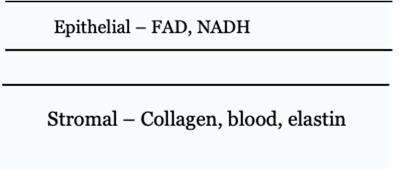

We have multiple data about the emissions of each of these fluorophores in the isetfluorescence repository.  We read them in and we also read in raw data taken from our subjects.  

Each of the fluorophores has several reports in the literature.  We chose which fluorophores to use in the script s_oeFluorophoreBasis.mlx.

This script will explore how we might create basis functions to predict the raw data as weighted sums of the fluorophore excitations, but combining them as if some of the fluorophores are passing through blood.

The reason we think blood is necessary is because the raw data - directory spectral photometry measures from the tongue and lip - show some signs of the dips that are well known to be part of the blood absorbance (transmittance) measured in different contexts.

To support the calculations of absorbance and transmittance we created a Matlab class called 'medium', which helps us keep track of the relationship between absorbance, absorptance, transmittance and optical density.

## Programming notes

Repositories: isetcam, isetfluorescence and oe_tongue_lip

3/4 of the blood is oxygenated.  We might add in deoxy_ in the future.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';

## Select the fluorophores and read oxy medium

Above, we plasted all the fluorophore emissions data in a matrix (fluorophores).  We check how well the full matrix can predict the data samples.  We think it won't without accounting for blood.  

The formula is simple for the full linear calculation


$$d=\textrm{Fw}$$


We have many fluorophore files from the literature. These are analyzed in s_LoadFluorophoreEmissions.  

Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  They exact emissions differ between labs, but the slopes are similar.

For the tongue, there is keratin, porphyrins, or chlorophyll.  We selected which to use in the s_oeBloodFluorophoreBasis.mlx script.

% This is from the lip.  It doesn't work as well for the tongue. 
% fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor'};

% We added some keratin. Not great
% fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor','KeratinWuQu'};
% fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor'};
fluorophoreNames = {'collagen1','elastin_webfluor','FADValdez'};

% fluorophoreNames = {'CollagenWuQu','elastin_webfluor','FADValdez'};
[fluorophores,wave] = fiLoadBasis(fluorophoreNames,'wave',wave);

% Here is oxy
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);


## Read in the oxy data

Let's amend the fluorophore basis by adding in collagen and elastin after some filtering by blood.  Notice that the blood has the two characteristic dips at 540 nm and 580nm.  We see little bumps like that in the raw data (above).

For different purposes we might choose different wavebands.  The raw data are pretty much good from 500-670 or so.  The wavelengths above 600 nm are mainly porphyrin fluorescence (bacteria on the tongue).

We only consider oxygenated blood now because 100% of the blood from the heart lung is oxygenated, and about 50% of the blood in the veins is also oxygenated. 

%{
ieNewGraphWin;
for od = (0.5:0.2:2)
    oxyblood.opticalDensity = od;
    plot(wave,oxyblood.transmittance); hold on;
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');
%}

## Apply blood transmittance

This should also become a function that takes a fluorophore and modifies it by blood transmittance with some arguments.  We experimented and it seemed we only needed elastin with a blood density of 2.5.  We might try using the fminsearch() method to fit the optical density.

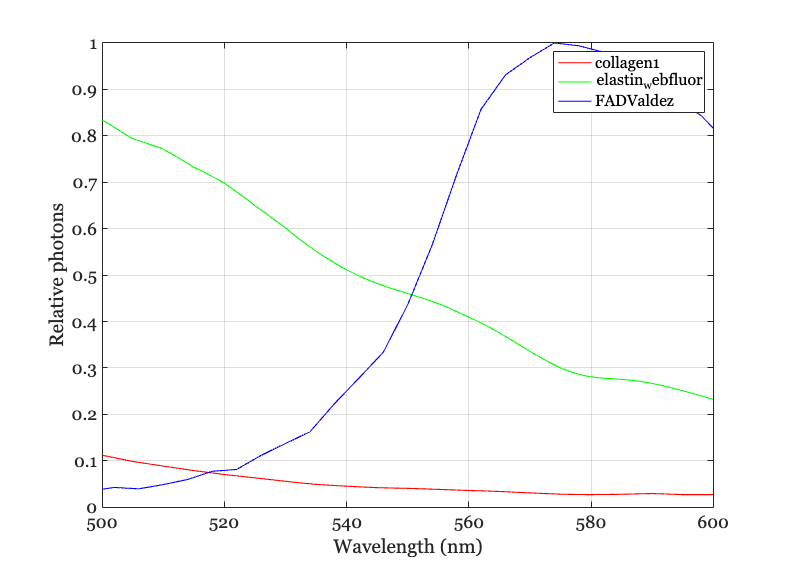

oxyblood.opticalDensity = 0.7;

transmittance = oxyblood.transmittance;

for ii = 1:numel(fluorophoreNames)
    if contains(lower(fluorophoreNames{ii}),'collagen') || ...
            contains(lower(fluorophoreNames{ii}),'elastin')
        fluorophores(:,ii) = fluorophores(:,ii).* transmittance(:);
    end
end

ieFigure;
for ii=1:size(fluorophores,2)
    plot(wave,fluorophores); hold on;
end
legend(fluorophoreNames);
xlabel('Wavelength (nm)'); ylabel('Relative photons'); grid on;

## Read database

This is the database of raw measurements.

[T,dataDir] = oeDatabaseCreate;

These are measurements with different excitation lights at max intensity.  All the subjects show the peak shift from 500 to 515 as the excitation light changes from 405 to 450.

Also, notice the very large dip on the lip around 580, but not on the tongue. 

Something to remember when we write.  When you measure samples, or with an endoscope, you may be able to see different fluorophores.  The global (raw) signal, however, may be dominated by one of the fluorophores with only relatively small contributions from the others.  In this case, it appears that collagen through oxygen is the dominant signal in 500-600 band.

## 405/415 nm excitation

subjects = {'Z','B','D','J'};
ieFigure;
tiledlayout(2,2);
disp(fluorophoreNames'); 

    {'collagen1'       }
    {'elastin_webfluor'}
    {'FADValdez'       }



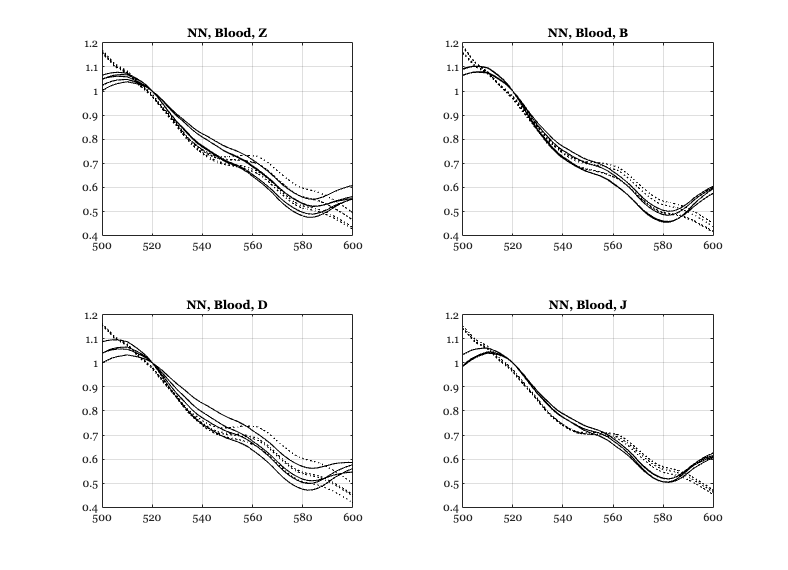

         0         0         0         0         0
    1.3939    1.3901    1.3772    1.3842    1.3855
    0.1703    0.1346    0.2125    0.1265    0.1738

         0    1.3587    1.0402         0
    1.3850    1.2351    1.2726    1.3805
    0.1560    0.1134    0.1087    0.1414

         0         0         0         0
    1.3889    1.3877    1.3793    1.3790
    0.1174    0.1581    0.2178    0.1537

         0         0         0         0
    1.3749    1.3616    1.3636    1.3583
    0.1615    0.1883    0.1867    0.1788



for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405,'e level',980);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415,'e level',910);
    tongueFiles = cat(1,files405,files415);

    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    disp(wgtsNN);
end

## 450 nm excitation light

subjects = {'Z','B','D','J'};
ieFigure;
tiledlayout(2,2);
disp(fluorophoreNames'); 

    {'collagen1'       }
    {'elastin_webfluor'}
    {'FADValdez'       }



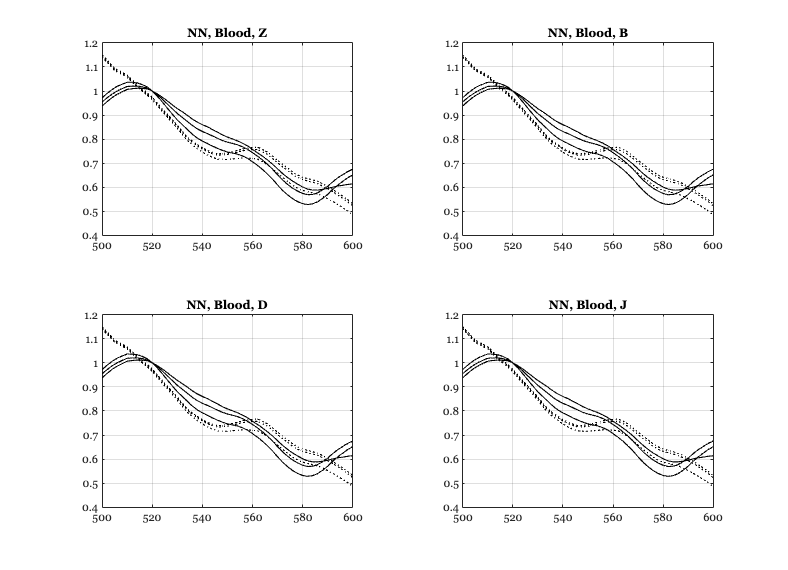

         0         0         0
    1.3656    1.3596    1.3570
    0.2618    0.2536    0.2089

         0         0         0
    1.3656    1.3596    1.3570
    0.2618    0.2536    0.2089

         0         0         0
    1.3656    1.3596    1.3570
    0.2618    0.2536    0.2089

         0         0         0
    1.3656    1.3596    1.3570
    0.2618    0.2536    0.2089



for ii=1:numel(subjects)
    files450 = ieTableGet(T,'substrate','tongue','e wave',450,'e level',870);
    tongueData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);    
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    disp(wgtsNN);
end